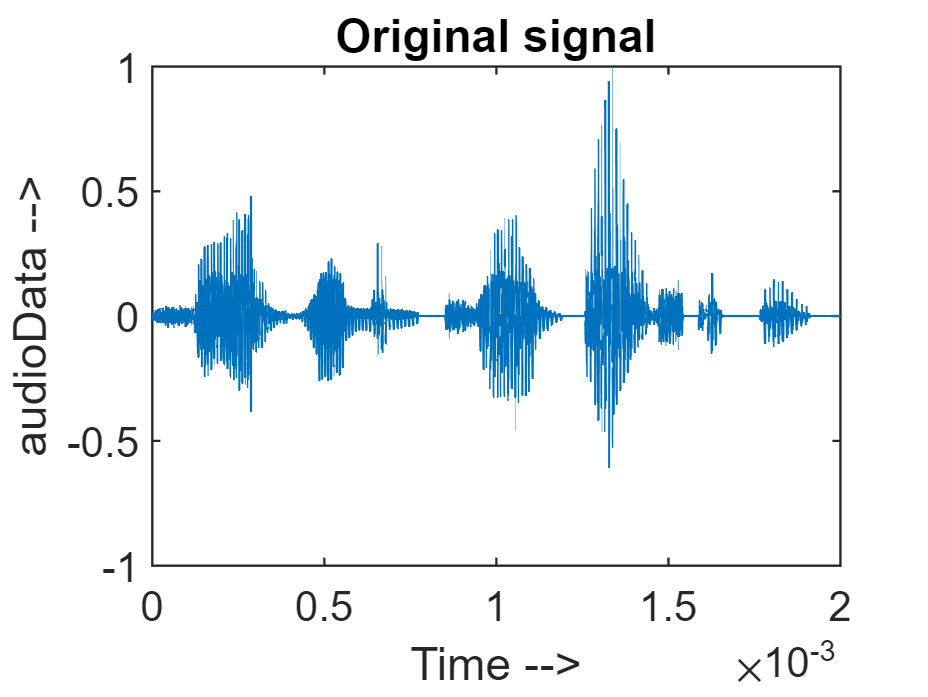

[audioData,fs] = audioread("fivewo.wav");
%soundsc(audioData,fs)
pow = bandpower(audioData);
pow = 20*log10(pow);
T = 0.002;
t = 0: (1/(800*fs)): T;
n = length(t);
fshift = (-n/2:n/2-1)*(fs/n);

plot(t, audioData)
title('Original signal')
xlabel('Time -->')
ylabel('audioData -->')

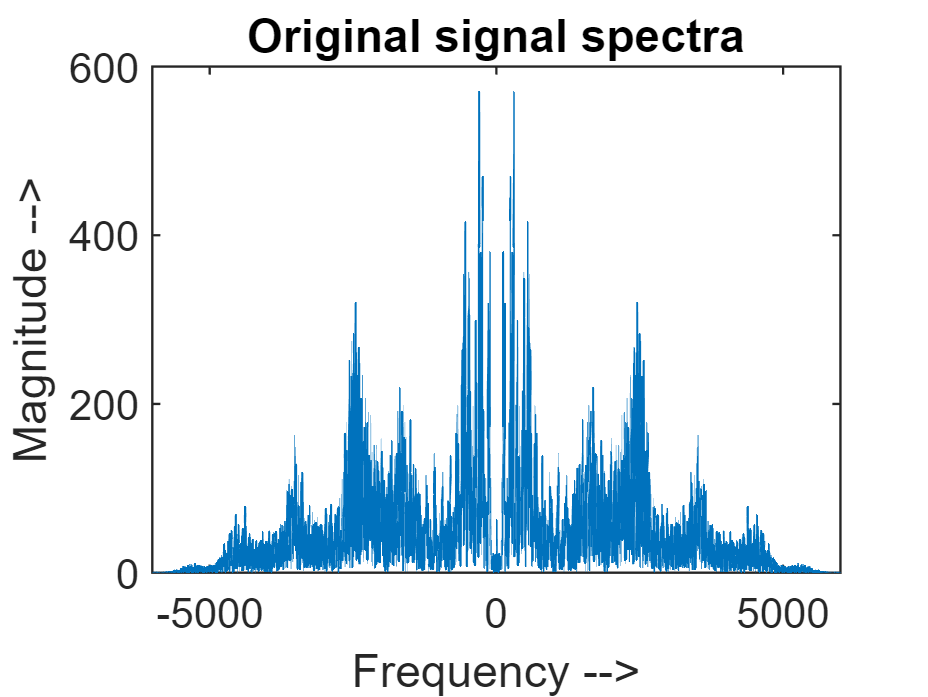


audio_fft = fftshift(fft(audioData));
audio_fft = abs(audio_fft);
plot(fshift,audio_fft);
xlim([-6000,6000]);
title('Original signal spectra')
xlabel('Frequency -->')
ylabel('Magnitude -->')


white_noise = wgn(length(audioData),1,pow);


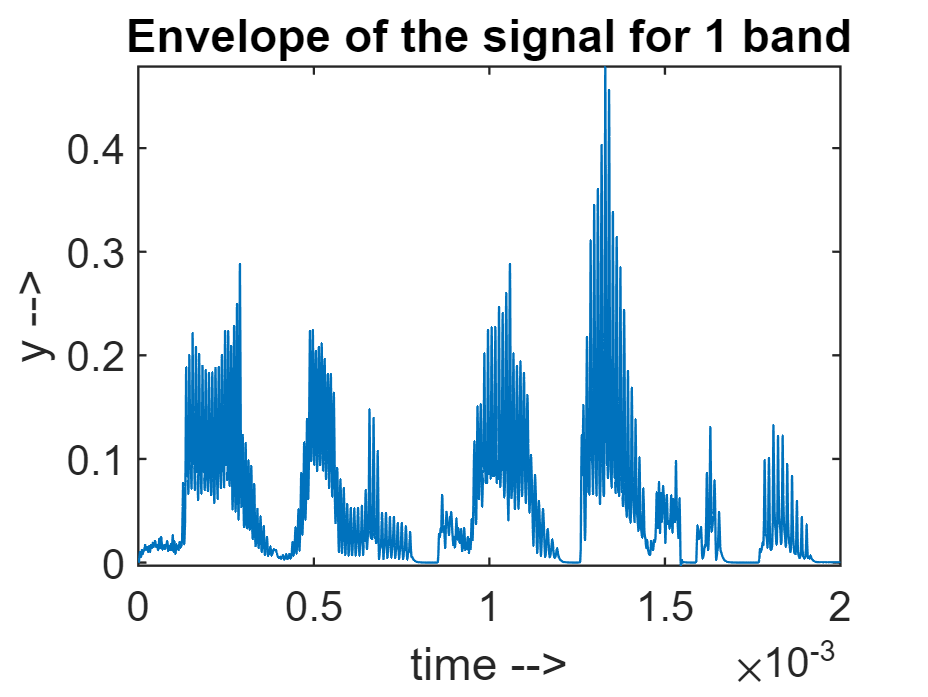

%1 band
[b,a] = butter(4,[90/(fs/2) 5760/(fs/2)],'bandpass'); %Band-pass 4th order butterworth filter
y = filter(b,a,audioData); %filtering
wn1 = filter(b,a,white_noise);

y_out = hilbert(y); %hibert transform
yo = abs(y_out);    %Magnitude

[bo,ao] = butter(4 ,240/(fs/2) ,'low'); %Low-pass filter
envelope = filter(bo, ao, yo);%Detected message signal
envelopeb1 = envelope;

plot(t, envelope) %Plotting envelope
title('Envelope of the signal for 1 band')
xlabel('time -->')
ylabel('y -->')

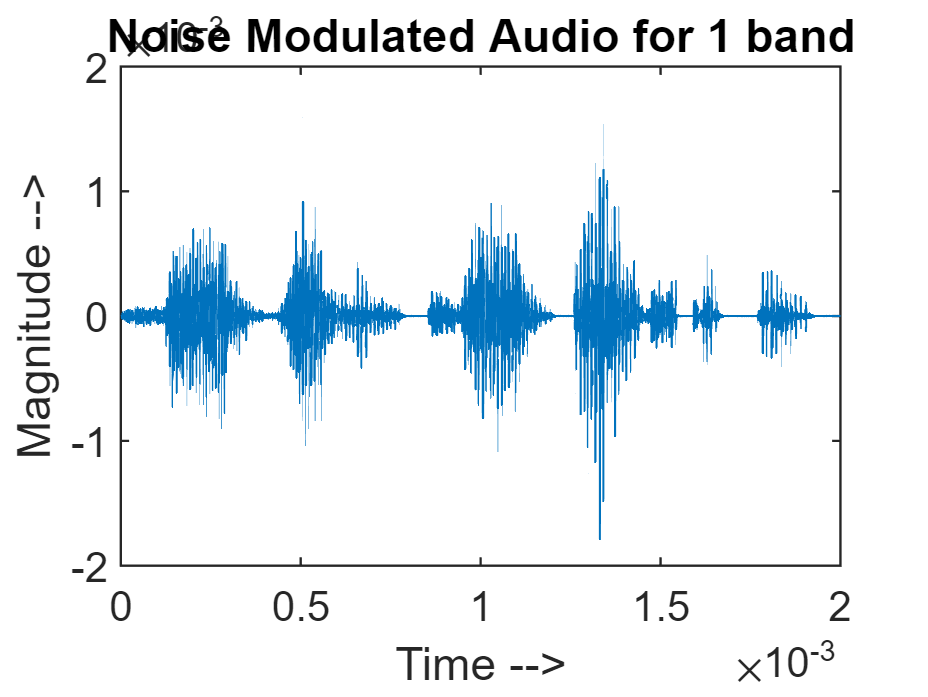


recons_audio = envelope.*wn1;
plot(t,recons_audio)
title('Noise Modulated Audio for 1 band')
xlabel('Time -->')
ylabel('Magnitude -->')

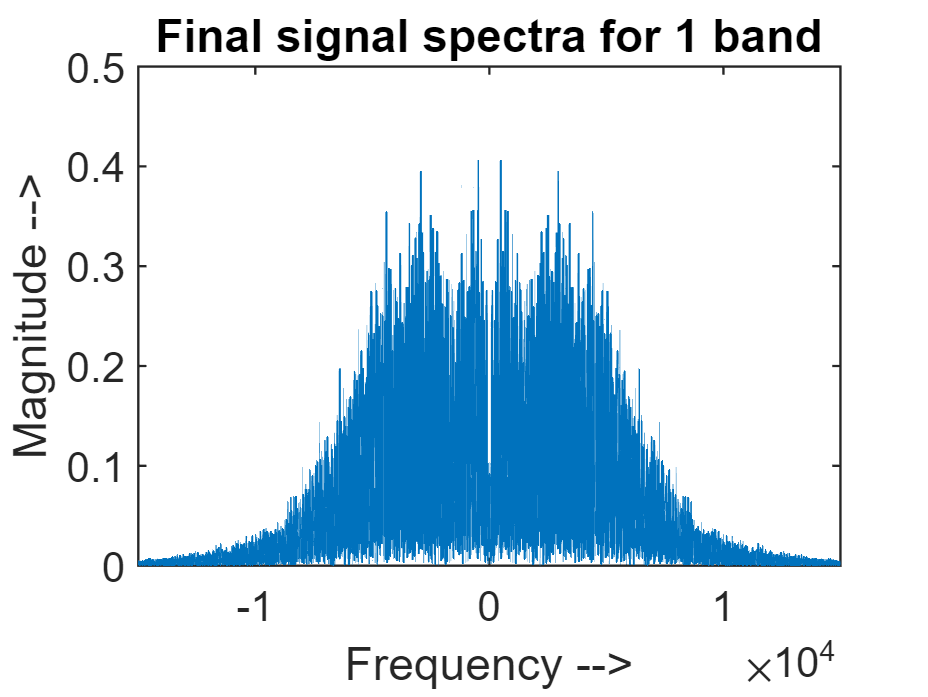

audio_fft = fftshift(fft(recons_audio));
audio_fft = abs(audio_fft);
plot(fshift,audio_fft);
xlim([-15000,15000]);
title('Final signal spectra for 1 band')
xlabel('Frequency -->')
ylabel('Magnitude -->')


audiowrite('test1.wav',recons_audio,fs); %Saving results


%output
% [audio_out,fs] = audioread("test1.wav");
% soundsc(audio_out,fs)

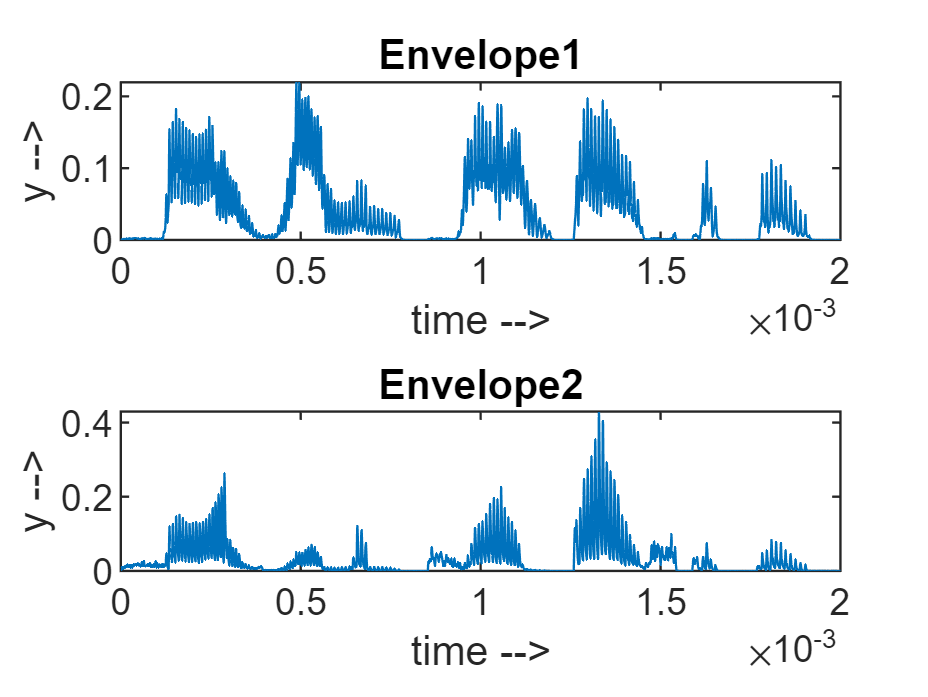

%2 bands
z = 90*(8.^(0:2)); %2 logarithmically spaced bandss
[b1,a1] = butter(2,[z(1)/(fs/2) z(2)/(fs/2)],'bandpass'); 
y1 = filter(b1,a1,audioData);
wn1 = filter(b1,a1,white_noise);

[b2,a2] = butter(2,[z(2)/(fs/2) z(3)/(fs/2)],'bandpass'); 
y2 = filter(b2,a2,audioData); 
wn2 = filter(b2,a2,white_noise);

y_out1 = hilbert(y1); %hibert transform
yo1 = abs(y_out1);    %Magnitude
y_out2 = hilbert(y2); %hibert transform
yo2 = abs(y_out2);    %Magnitude

[bo,ao] = butter(2 ,240/(fs/2) ,'low'); %Low-pass filter
envelope1 = filter(bo, ao, yo1);%Detected message signal
envelope2 = filter(bo, ao, yo2);
final_envelope = envelope1 + envelope2;
envelopeb2 = final_envelope;

recons_audiop1 = envelope1.*wn1;
recons_audiop2 = envelope2.*wn2;

%Plotting envelopes
figure(1);
subplot(2,1,1)
plot(t, envelope1) 
title('Envelope1')
xlabel('time -->')
ylabel('y -->')
subplot(2,1,2)
plot(t, envelope2) 
title('Envelope2')
xlabel('time -->')
ylabel('y -->')

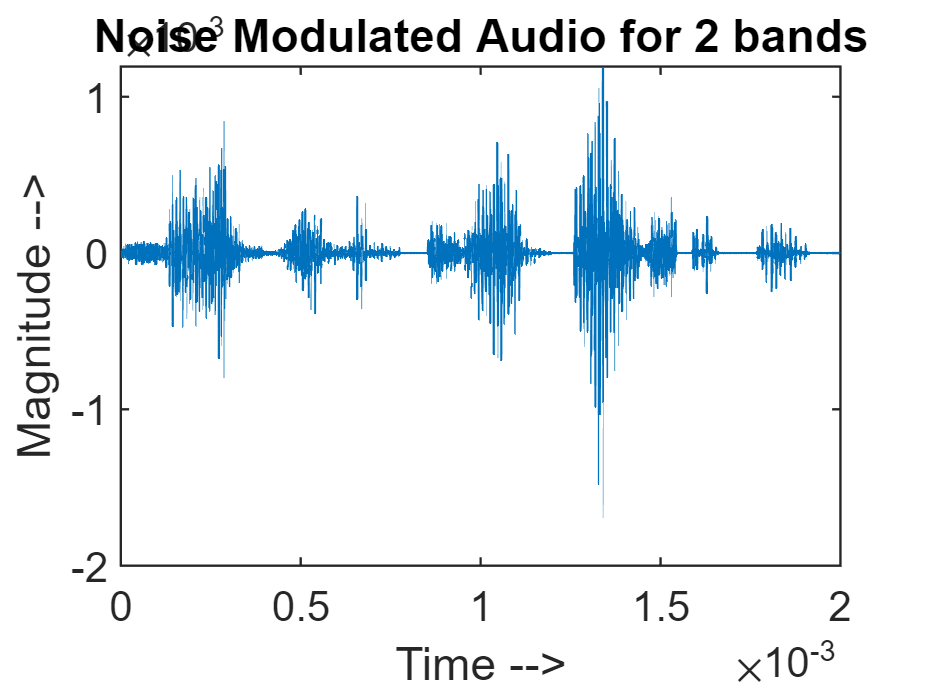


recons_audio = recons_audiop1+recons_audiop2;
figure(2);
plot(t,recons_audio)
title('Noise Modulated Audio for 2 bands')
xlabel('Time -->')
ylabel('Magnitude -->')

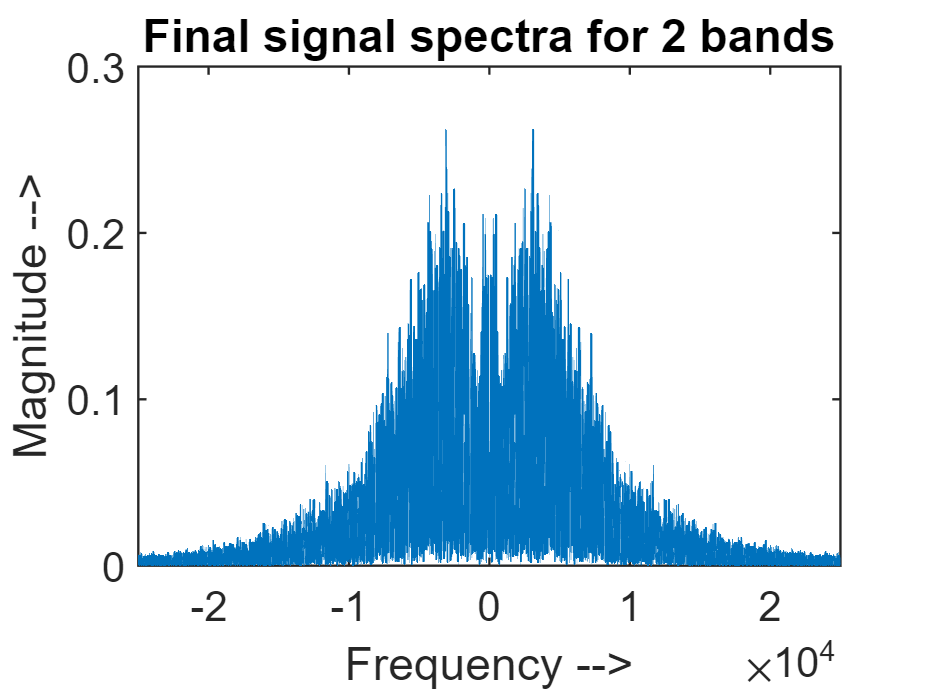

audio_fft = fftshift(fft(recons_audio));
audio_fft = abs(audio_fft);
plot(fshift,audio_fft);
xlim([-25000,25000]);
title('Final signal spectra for 2 bands')
xlabel('Frequency -->')
ylabel('Magnitude -->')


audiowrite('test2.wav',envelope,fs); %Saving results

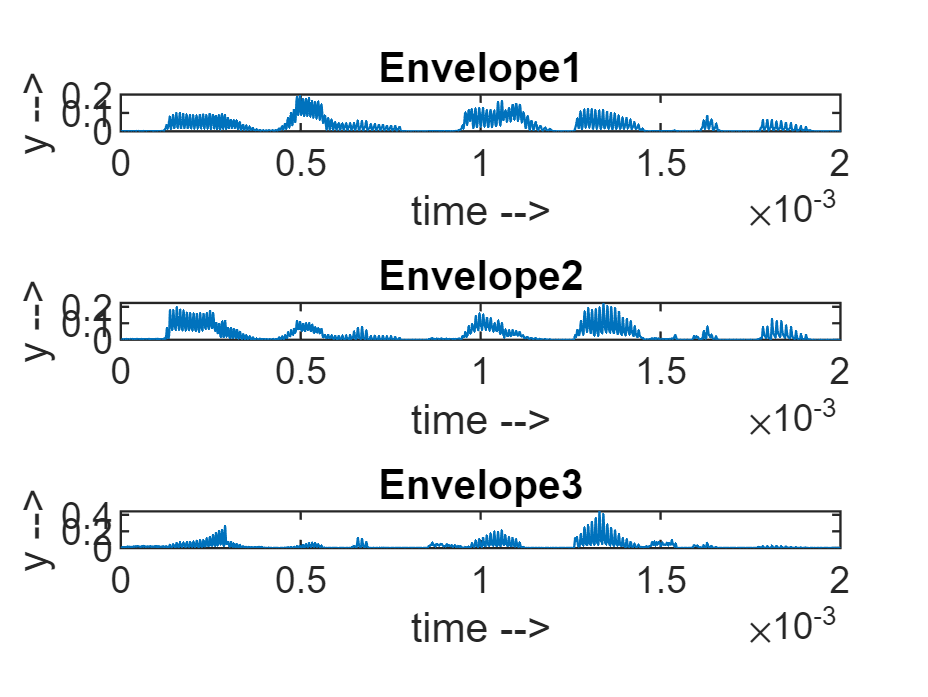

%3 bands
z = 90*4.^(0:3); %2 logarithmically spaced bandss
[b1,a1] = butter(2,[z(1)/(fs/2) z(2)/(fs/2)],'bandpass'); 
y1 = filter(b1,a1,audioData); 
wn1 = filter(b1,a1,white_noise);
[b2,a2] = butter(2,[z(2)/(fs/2) z(3)/(fs/2)],'bandpass'); 
y2 = filter(b2,a2,audioData);  
wn2 = filter(b2,a2,white_noise);
[b3,a3] = butter(2,[z(3)/(fs/2) z(4)/(fs/2)],'bandpass'); 
y3 = filter(b3,a3,audioData);  
wn3 = filter(b3,a3,white_noise);

y_out1 = hilbert(y1); 
yo1 = abs(y_out1);    
y_out2 = hilbert(y2); 
yo2 = abs(y_out2);    
y_out3 = hilbert(y3); 
yo3 = abs(y_out3);    

[bo,ao] = butter(4 ,240/(fs/2) ,'low'); %Low-pass filter
envelope1 = filter(bo, ao, yo1);%Detected message signal
envelope2 = filter(bo, ao, yo2);
envelope3 = filter(bo, ao, yo3);
final_envelope = envelope1 + envelope2 +envelope3;
envelopeb3 = final_envelope;

recons_audiop1 = envelope1.*wn1;
recons_audiop2 = envelope2.*wn2;
recons_audiop3 = envelope3.*wn3;

%Plotting envelopes
figure(3);
subplot(3,1,1)
plot(t, envelope1) 
title('Envelope1')
xlabel('time -->')
ylabel('y -->')
subplot(3,1,2)
plot(t, envelope2) 
title('Envelope2')
xlabel('time -->')
ylabel('y -->')
subplot(3,1,3)
plot(t, envelope3) 
title('Envelope3')
xlabel('time -->')
ylabel('y -->')

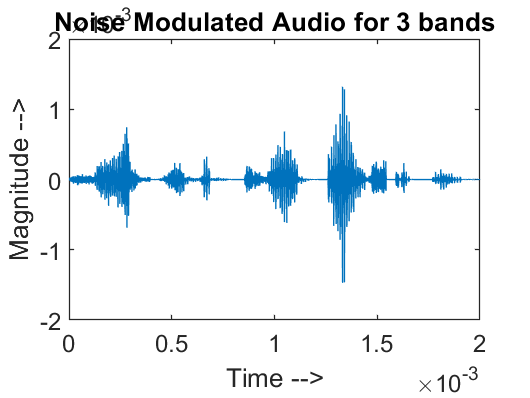


recons_audio = recons_audiop1+recons_audiop2+recons_audiop3;
figure(4);
plot(t,recons_audio)
title('Noise Modulated Audio for 3 bands')
xlabel('Time -->')
ylabel('Magnitude -->')

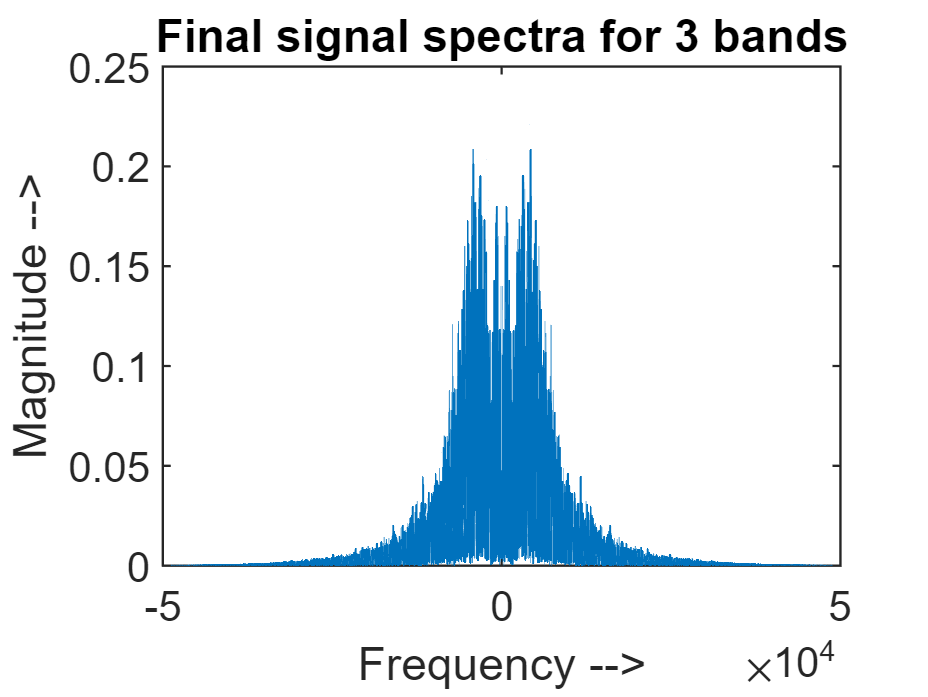

audio_fft = fftshift(fft(recons_audio));
audio_fft = abs(audio_fft);
plot(fshift,audio_fft);
xlim([-50000,50000]);
title('Final signal spectra for 3 bands')
xlabel('Frequency -->')
ylabel('Magnitude -->')


audiowrite('test3.wav',envelope,fs); %Saving results

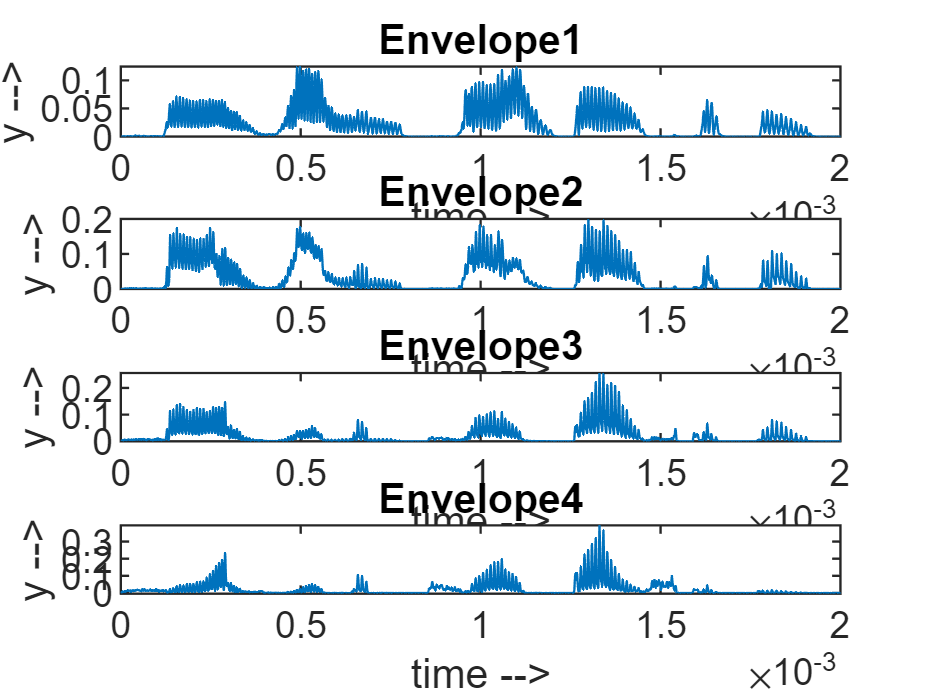

%4 bands
z =  90*((2^1.5).^(0:4));%2 logarithmically spaced bandss
[b1,a1] = butter(2,[z(1)/(fs/2) z(2)/(fs/2)],'bandpass'); 
y1 = filter(b1,a1,audioData); 
wn1 = filter(b1,a1,white_noise);
[b2,a2] = butter(2,[z(2)/(fs/2) z(3)/(fs/2)],'bandpass'); 
y2 = filter(b2,a2,audioData); 
wn2 = filter(b2,a2,white_noise);
[b3,a3] = butter(2,[z(3)/(fs/2) z(4)/(fs/2)],'bandpass'); 
y3 = filter(b3,a3,audioData); 
wn3 = filter(b3,a3,white_noise);
[b4,a4] = butter(2,[z(4)/(fs/2) z(5)/(fs/2)],'bandpass'); 
y4 = filter(b4,a4,audioData); 
wn4 = filter(b4,a4,white_noise);

y_out1 = hilbert(y1); 
yo1 = abs(y_out1);    
y_out2 = hilbert(y2); 
yo2 = abs(y_out2);    
y_out3 = hilbert(y3); 
yo3 = abs(y_out3); 
y_out4 = hilbert(y4); 
yo4 = abs(y_out4); 

[bo,ao] = butter(4 ,240/(fs/2) ,'low'); %Low-pass filter
envelope1 = filter(bo, ao, yo1);%Detected message signal
envelope2 = filter(bo, ao, yo2);
envelope3 = filter(bo, ao, yo3);
envelope4 = filter(bo, ao, yo4);
final_envelope = envelope1 + envelope2 +envelope3 + envelope4;
envelopeb4 = final_envelope;

recons_audiop1 = envelope1.*wn1;
recons_audiop2 = envelope2.*wn2;
recons_audiop3 = envelope3.*wn3;
recons_audiop4 = envelope4.*wn4;

%Plotting envelopes
figure(5);
subplot(4,1,1)
plot(t, envelope1) 
title('Envelope1')
xlabel('time -->')
ylabel('y -->')
subplot(4,1,2)
plot(t, envelope2) 
title('Envelope2')
xlabel('time -->')
ylabel('y -->')
subplot(4,1,3)
plot(t, envelope3) 
title('Envelope3')
xlabel('time -->')
ylabel('y -->')
subplot(4,1,4)
plot(t, envelope4) 
title('Envelope4')
xlabel('time -->')
ylabel('y -->')

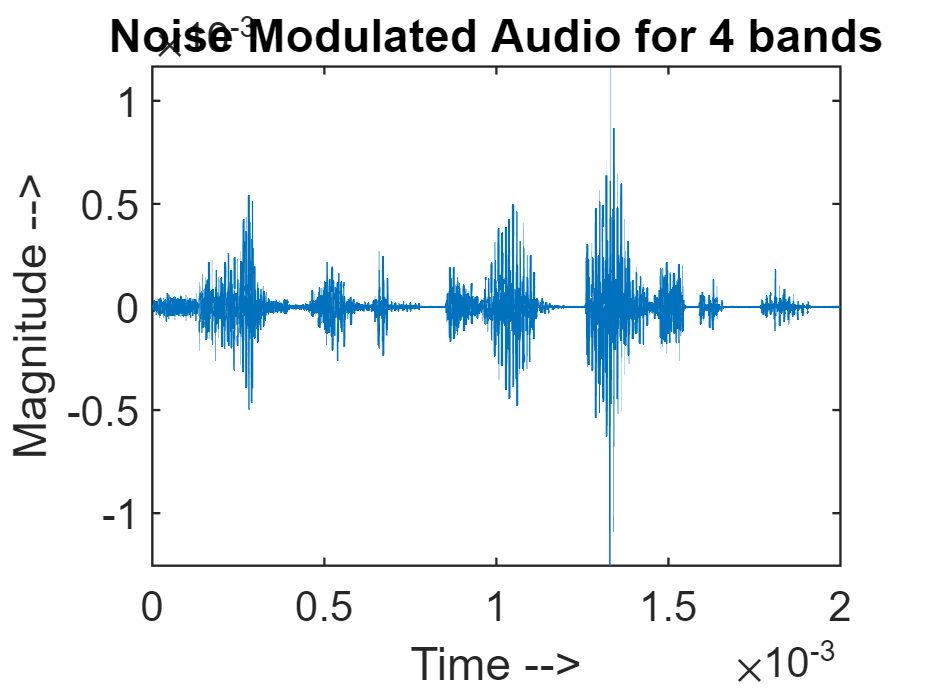


recons_audio = recons_audiop1+recons_audiop2+recons_audiop3+recons_audiop4;
figure(6);
plot(t,recons_audio)
title('Noise Modulated Audio for 4 bands')
xlabel('Time -->')
ylabel('Magnitude -->')

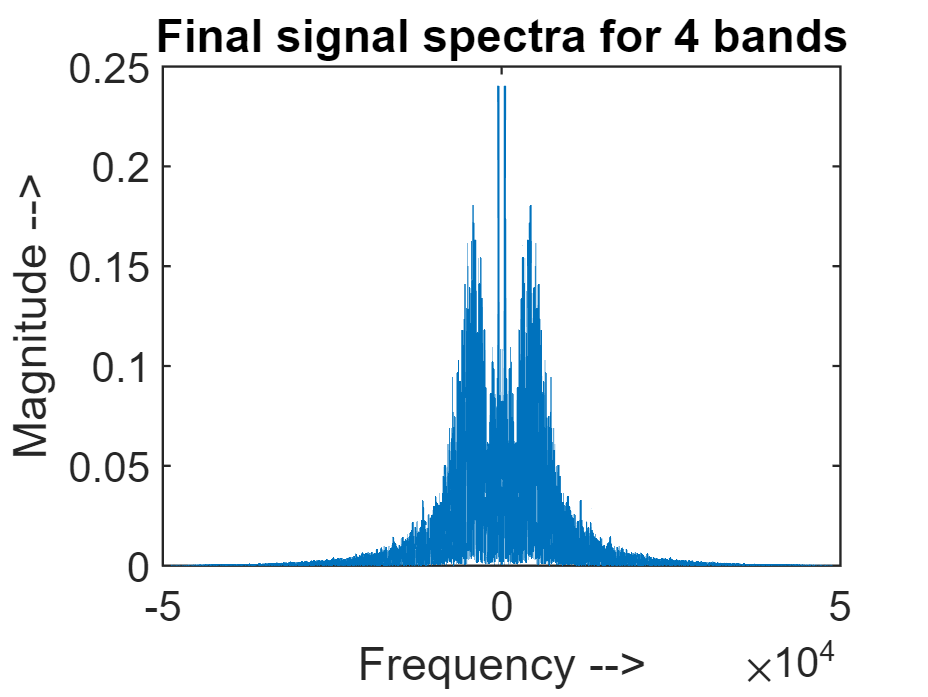

audio_fft = fftshift(fft(recons_audio));
audio_fft = abs(audio_fft);
plot(fshift,audio_fft);
xlim([-50000,50000]);
title('Final signal spectra for 4 bands')
xlabel('Frequency -->')
ylabel('Magnitude -->')


audiowrite('test4.wav',envelope,fs); %Saving results

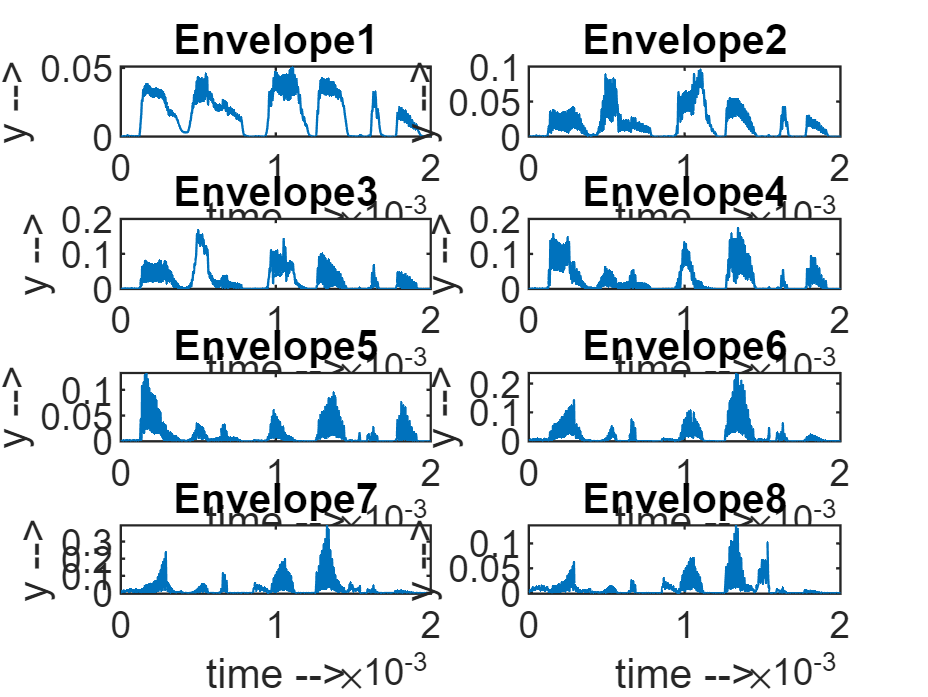

%8 bands
z =  90*((2^0.75).^(0:8)); %2 logarithmically spaced bandss
[b1,a1] = butter(2,[z(1)/(fs/2) z(2)/(fs/2)],'bandpass'); 
y1 = filter(b1,a1,audioData); 
wn1 = filter(b1,a1,white_noise);
[b2,a2] = butter(2,[z(2)/(fs/2) z(3)/(fs/2)],'bandpass'); 
y2 = filter(b2,a2,audioData); 
wn2 = filter(b2,a2,white_noise);
[b3,a3] = butter(2,[z(3)/(fs/2) z(4)/(fs/2)],'bandpass'); 
y3 = filter(b3,a3,audioData); 
wn3 = filter(b3,a3,white_noise);
[b4,a4] = butter(2,[z(4)/(fs/2) z(5)/(fs/2)],'bandpass'); 
y4 = filter(b4,a4,audioData); 
wn4 = filter(b4,a4,white_noise);
[b5,a5] = butter(2,[z(5)/(fs/2) z(6)/(fs/2)],'bandpass'); 
y5 = filter(b5,a5,audioData); 
wn5 = filter(b5,a5,white_noise);
[b6,a6] = butter(2,[z(6)/(fs/2) z(7)/(fs/2)],'bandpass'); 
y6 = filter(b6,a6,audioData); 
wn6 = filter(b6,a6,white_noise);
[b7,a7] = butter(2,[z(7)/(fs/2) z(8)/(fs/2)],'bandpass'); 
y7 = filter(b7,a7,audioData); 
wn7 = filter(b7,a7,white_noise);
[b8,a8] = butter(2,[z(8)/(fs/2) z(9)/(fs/2)],'bandpass'); 
y8 = filter(b8,a8,audioData); 
wn8 = filter(b8,a8,white_noise);

y_out1 = hilbert(y1); 
yo1 = abs(y_out1);    
y_out2 = hilbert(y2); 
yo2 = abs(y_out2);    
y_out3 = hilbert(y3); 
yo3 = abs(y_out3); 
y_out4 = hilbert(y4); 
yo4 = abs(y_out4); 
y_out5 = hilbert(y5); 
yo5 = abs(y_out5);    
y_out6 = hilbert(y6); 
yo6 = abs(y_out6);    
y_out7 = hilbert(y7); 
yo7 = abs(y_out7); 
y_out8 = hilbert(y8); 
yo8 = abs(y_out8); 


[bo,ao] = butter(4 ,240/(fs/2) ,'low'); %Low-pass filter
envelope1 = filter(bo, ao, yo1);%Detected message signal
envelope2 = filter(bo, ao, yo2);
envelope3 = filter(bo, ao, yo3);
envelope4 = filter(bo, ao, yo4);
envelope5 = filter(bo, ao, yo5);%Detected message signal
envelope6 = filter(bo, ao, yo6);
envelope7 = filter(bo, ao, yo7);
envelope8 = filter(bo, ao, yo8);
final_envelope = envelope1 + envelope2 +envelope3 + envelope4 + envelope5 + envelope6 +envelope7 + envelope8;
envelopeb8 = final_envelope;

recons_audiop1 = envelope1.*wn1;
recons_audiop2 = envelope2.*wn2;
recons_audiop3 = envelope3.*wn3;
recons_audiop4 = envelope4.*wn4;
recons_audiop5 = envelope5.*wn5;
recons_audiop6 = envelope6.*wn6;
recons_audiop7 = envelope7.*wn7;
recons_audiop8 = envelope8.*wn8;

%Plotting envelopes
figure(7);
subplot(4,2,1)
plot(t, envelope1) 
title('Envelope1')
xlabel('time -->')
ylabel('y -->')
subplot(4,2,2)
plot(t, envelope2) 
title('Envelope2')
xlabel('time -->')
ylabel('y -->')
subplot(4,2,3)
plot(t, envelope3) 
title('Envelope3')
xlabel('time -->')
ylabel('y -->')
subplot(4,2,4)
plot(t, envelope4) 
title('Envelope4')
xlabel('time -->')
ylabel('y -->')
subplot(4,2,5)
plot(t, envelope5) 
title('Envelope5')
xlabel('time -->')
ylabel('y -->')
subplot(4,2,6)
plot(t, envelope6) 
title('Envelope6')
xlabel('time -->')
ylabel('y -->')
subplot(4,2,7)
plot(t, envelope7) 
title('Envelope7')
xlabel('time -->')
ylabel('y -->')
subplot(4,2,8)
plot(t, envelope8) 
title('Envelope8')
xlabel('time -->')
ylabel('y -->')

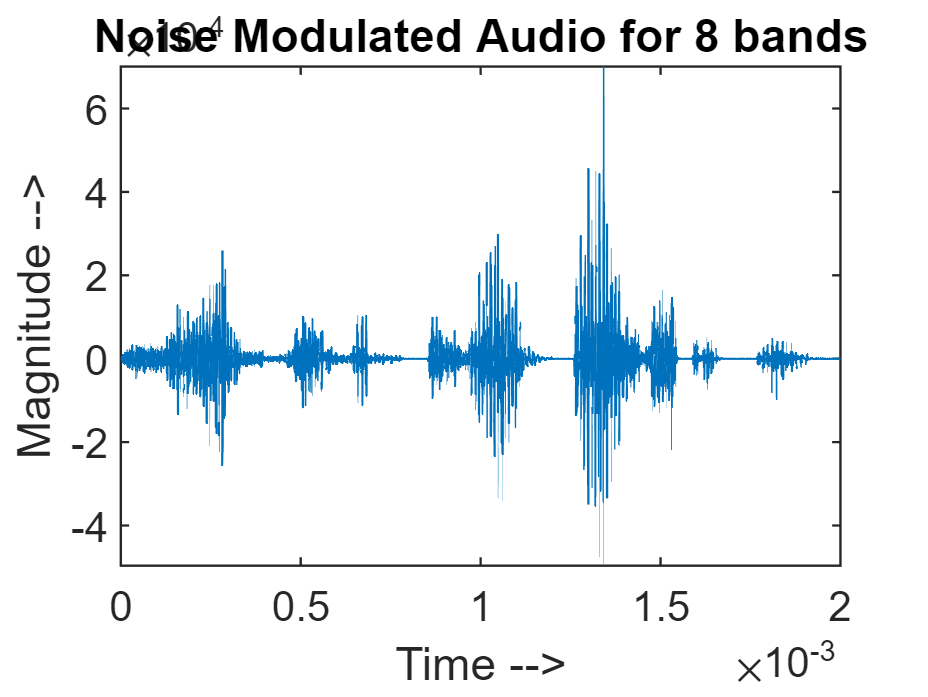


recons_audio = recons_audiop1+recons_audiop2+recons_audiop3+recons_audiop4+recons_audiop5+recons_audiop6+recons_audiop7+recons_audiop8;
figure(8);
plot(t,recons_audio)
title('Noise Modulated Audio for 8 bands')
xlabel('Time -->')
ylabel('Magnitude -->')

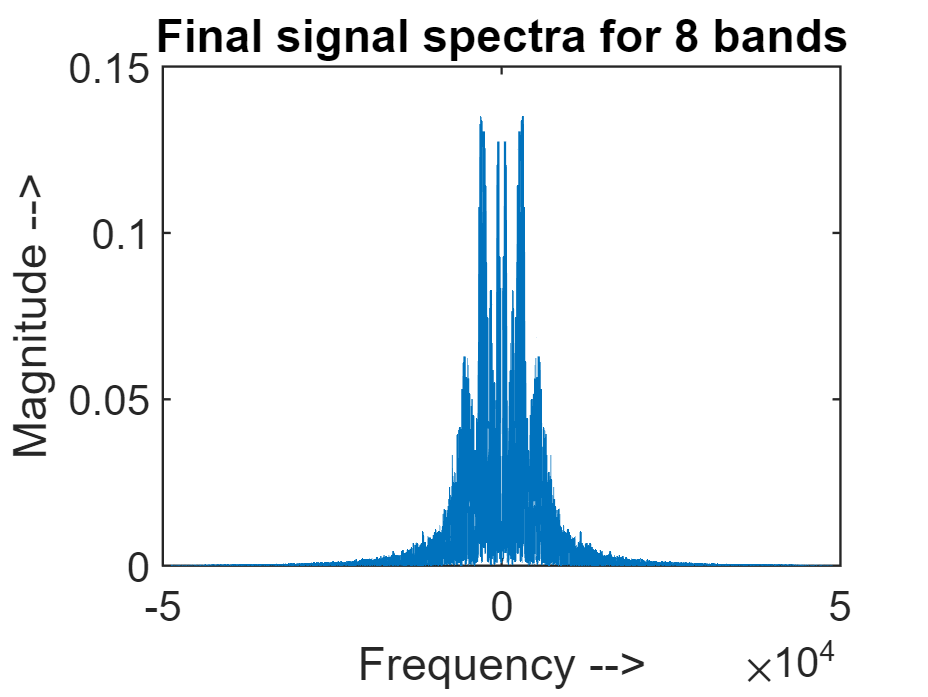

audio_fft = fftshift(fft(recons_audio));
audio_fft = abs(audio_fft);
plot(fshift,audio_fft);
xlim([-50000,50000]);
title('Final signal spectra for 8 bands')
xlabel('Frequency -->')
ylabel('Magnitude -->')


audiowrite('test8.wav',envelope,fs); %Saving results

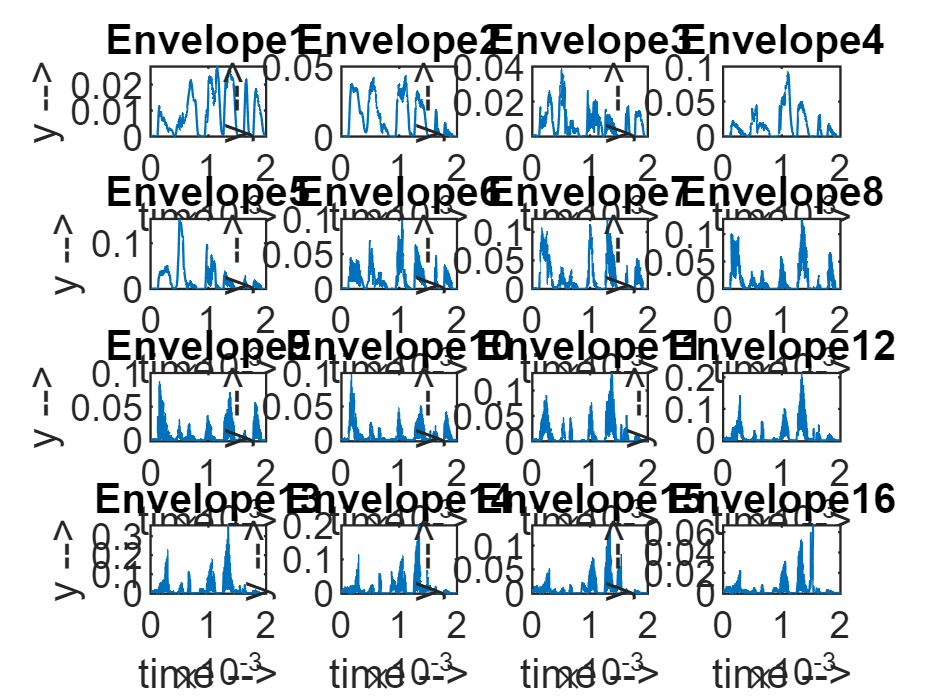

%16 bands
z =  90*((2^0.375).^(0:16)); %2 logarithmically spaced bandss
[b1,a1] = butter(2,[z(1)/(fs/2) z(2)/(fs/2)],'bandpass'); 
y1 = filter(b1,a1,audioData); 
wn1 = filter(b1,a1,white_noise);
[b2,a2] = butter(2,[z(2)/(fs/2) z(3)/(fs/2)],'bandpass'); 
y2 = filter(b2,a2,audioData); 
wn2 = filter(b2,a2,white_noise);
[b3,a3] = butter(2,[z(3)/(fs/2) z(4)/(fs/2)],'bandpass'); 
y3 = filter(b3,a3,audioData); 
wn3 = filter(b3,a3,white_noise);
[b4,a4] = butter(2,[z(4)/(fs/2) z(5)/(fs/2)],'bandpass'); 
y4 = filter(b4,a4,audioData); 
wn4 = filter(b4,a4,white_noise);
[b5,a5] = butter(2,[z(5)/(fs/2) z(6)/(fs/2)],'bandpass'); 
y5 = filter(b5,a5,audioData); 
wn5 = filter(b5,a5,white_noise);
[b6,a6] = butter(2,[z(6)/(fs/2) z(7)/(fs/2)],'bandpass'); 
y6 = filter(b6,a6,audioData); 
wn6 = filter(b6,a6,white_noise);
[b7,a7] = butter(2,[z(7)/(fs/2) z(8)/(fs/2)],'bandpass'); 
y7 = filter(b7,a7,audioData); 
wn7 = filter(b7,a7,white_noise);
[b8,a8] = butter(2,[z(8)/(fs/2) z(9)/(fs/2)],'bandpass'); 
y8 = filter(b8,a8,audioData); 
wn8 = filter(b8,a8,white_noise);
[b9,a9] = butter(2,[z(9)/(fs/2) z(10)/(fs/2)],'bandpass'); 
y9 = filter(b9,a9,audioData); 
wn9 = filter(b9,a9,white_noise);
[b10,a10] = butter(2,[z(10)/(fs/2) z(11)/(fs/2)],'bandpass'); 
y10 = filter(b10,a10,audioData); 
wn10 = filter(b10,a10,white_noise);
[b11,a11] = butter(2,[z(11)/(fs/2) z(12)/(fs/2)],'bandpass'); 
y11 = filter(b11,a11,audioData); 
wn11 = filter(b11,a11,white_noise);
[b12,a12] = butter(2,[z(12)/(fs/2) z(13)/(fs/2)],'bandpass'); 
y12 = filter(b12,a12,audioData);
wn12 = filter(b12,a12,white_noise); 
[b13,a13] = butter(2,[z(13)/(fs/2) z(14)/(fs/2)],'bandpass'); 
y13 = filter(b13,a13,audioData); 
wn13 = filter(b13,a13,white_noise);
[b14,a14] = butter(2,[z(14)/(fs/2) z(15)/(fs/2)],'bandpass'); 
y14 = filter(b14,a14,audioData); 
wn14 = filter(b14,a14,white_noise);
[b15,a15] = butter(2,[z(15)/(fs/2) z(16)/(fs/2)],'bandpass'); 
y15 = filter(b15,a15,audioData); 
wn15 = filter(b15,a15,white_noise);
[b16,a16] = butter(2,[z(16)/(fs/2) z(17)/(fs/2)],'bandpass'); 
y16 = filter(b16,a16,audioData);
wn16 = filter(b16,a16,white_noise); 

y_out1 = hilbert(y1); 
yo1 = abs(y_out1);    
y_out2 = hilbert(y2); 
yo2 = abs(y_out2);    
y_out3 = hilbert(y3); 
yo3 = abs(y_out3); 
y_out4 = hilbert(y4); 
yo4 = abs(y_out4); 
y_out5 = hilbert(y5); 
yo5 = abs(y_out5);    
y_out6 = hilbert(y6); 
yo6 = abs(y_out6);    
y_out7 = hilbert(y7); 
yo7 = abs(y_out7); 
y_out8 = hilbert(y8); 
yo8 = abs(y_out8); 
y_out9 = hilbert(y9); 
yo9 = abs(y_out9);    
y_out10 = hilbert(y10); 
yo10 = abs(y_out10);    
y_out11 = hilbert(y11); 
yo11 = abs(y_out11); 
y_out12 = hilbert(y12); 
yo12 = abs(y_out12); 
y_out13 = hilbert(y13); 
yo13 = abs(y_out13);    
y_out14 = hilbert(y14); 
yo14 = abs(y_out14);    
y_out15 = hilbert(y15); 
yo15 = abs(y_out15); 
y_out16 = hilbert(y16); 
yo16 = abs(y_out16); 


[bo,ao] = butter(4 ,240/(fs/2) ,'low'); %Low-pass filter
envelope1 = filter(bo, ao, yo1);%Detected message signal
envelope2 = filter(bo, ao, yo2);
envelope3 = filter(bo, ao, yo3);
envelope4 = filter(bo, ao, yo4);
envelope5 = filter(bo, ao, yo5);%Detected message signal
envelope6 = filter(bo, ao, yo6);
envelope7 = filter(bo, ao, yo7);
envelope8 = filter(bo, ao, yo8);
envelope9 = filter(bo, ao, yo9);%Detected message signal
envelope10 = filter(bo, ao, yo10);
envelope11 = filter(bo, ao, yo11);
envelope12 = filter(bo, ao, yo12);
envelope13 = filter(bo, ao, yo13);%Detected message signal
envelope14 = filter(bo, ao, yo14);
envelope15 = filter(bo, ao, yo15);
envelope16 = filter(bo, ao, yo16);
final_envelope = envelope1 + envelope2 +envelope3 + envelope4 + envelope5 + envelope6 +envelope7 + envelope8 +envelope9 + envelope10 +envelope11 + envelope12 + envelope13 + envelope14 +envelope15 + envelope16;
envelopeb16 = final_envelope;

recons_audiop1 = envelope1.*wn1;
recons_audiop2 = envelope2.*wn2;
recons_audiop3 = envelope3.*wn3;
recons_audiop4 = envelope4.*wn4;
recons_audiop5 = envelope5.*wn5;
recons_audiop6 = envelope6.*wn6;
recons_audiop7 = envelope7.*wn7;
recons_audiop8 = envelope8.*wn8;
recons_audiop9 = envelope9.*wn9;
recons_audiop10 = envelope10.*wn10;
recons_audiop11 = envelope11.*wn11;
recons_audiop12 = envelope12.*wn12;
recons_audiop13 = envelope13.*wn13;
recons_audiop14 = envelope14.*wn14;
recons_audiop15 = envelope15.*wn15;
recons_audiop16 = envelope16.*wn16;

%Plotting envelopes
figure(9);
subplot(4,4,1)
plot(t, envelope1) 
title('Envelope1')
xlabel('time -->')
ylabel('y -->')
subplot(4,4,2)
plot(t, envelope2) 
title('Envelope2')
xlabel('time -->')
ylabel('y -->')
subplot(4,4,3)
plot(t, envelope3) 
title('Envelope3')
xlabel('time -->')
ylabel('y -->')
subplot(4,4,4)
plot(t, envelope4) 
title('Envelope4')
xlabel('time -->')
ylabel('y -->')
subplot(4,4,5)
plot(t, envelope5) 
title('Envelope5')
xlabel('time -->')
ylabel('y -->')
subplot(4,4,6)
plot(t, envelope6) 
title('Envelope6')
xlabel('time -->')
ylabel('y -->')
subplot(4,4,7)
plot(t, envelope7) 
title('Envelope7')
xlabel('time -->')
ylabel('y -->')
subplot(4,4,8)
plot(t, envelope8) 
title('Envelope8')
xlabel('time -->')
ylabel('y -->')
subplot(4,4,9)
plot(t, envelope9) 
title('Envelope9')
xlabel('time -->')
ylabel('y -->')
subplot(4,4,10)
plot(t, envelope10) 
title('Envelope10')
xlabel('time -->')
ylabel('y -->')
subplot(4,4,11)
plot(t, envelope11) 
title('Envelope11')
xlabel('time -->')
ylabel('y -->')
subplot(4,4,12)
plot(t, envelope12) 
title('Envelope12')
xlabel('time -->')
ylabel('y -->')
subplot(4,4,13)
plot(t, envelope13) 
title('Envelope13')
xlabel('time -->')
ylabel('y -->')
subplot(4,4,14)
plot(t, envelope14) 
title('Envelope14')
xlabel('time -->')
ylabel('y -->')
subplot(4,4,15)
plot(t, envelope15) 
title('Envelope15')
xlabel('time -->')
ylabel('y -->')
subplot(4,4,16)
plot(t, envelope16) 
title('Envelope16')
xlabel('time -->')
ylabel('y -->')

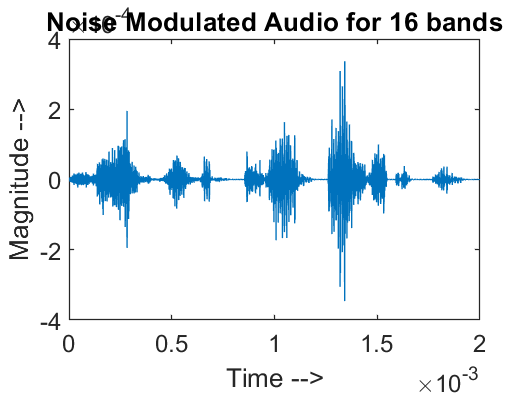


recons_audio = recons_audiop1+recons_audiop2+recons_audiop3+recons_audiop4+recons_audiop5+recons_audiop6+recons_audiop7+recons_audiop8+recons_audiop9+recons_audiop10+recons_audiop11+recons_audiop12+recons_audiop13+recons_audiop14+recons_audiop15+recons_audiop16;
figure(10);
plot(t,recons_audio)
title('Noise Modulated Audio for 16 bands')
xlabel('Time -->')
ylabel('Magnitude -->')

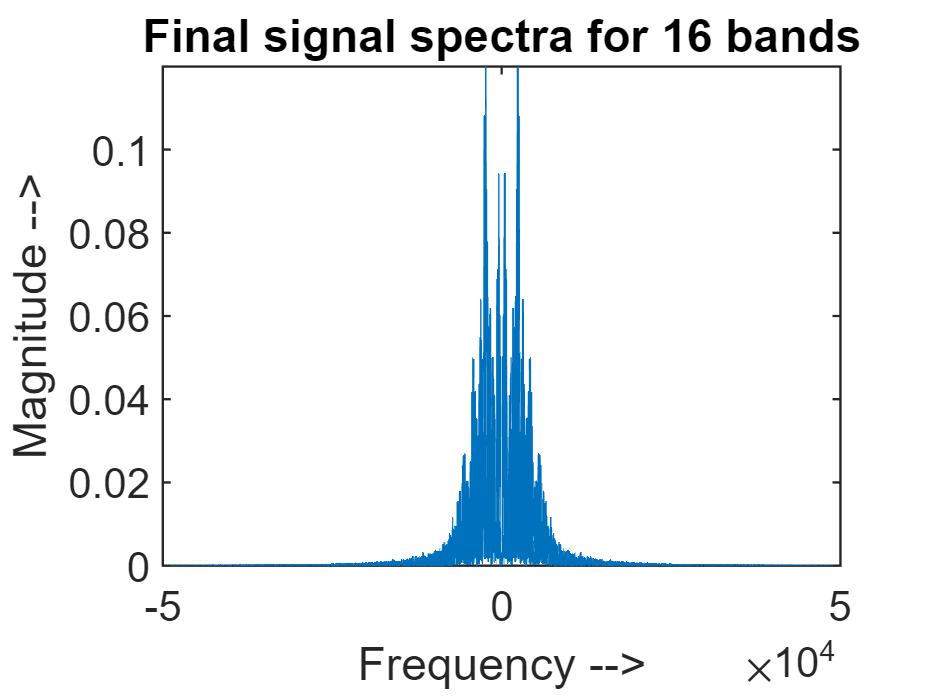

audio_fft = fftshift(fft(recons_audio));
audio_fft = abs(audio_fft);
figure(11);
plot(fshift,audio_fft);
xlim([-50000,50000]);
title('Final signal spectra for 16 bands')
xlabel('Frequency -->')
ylabel('Magnitude -->')


audiowrite('test16.wav',envelope,fs); %Saving results
[audio_out,fs] = audioread("test16.wav");
soundsc(audio_out,fs)